close all, clear all, clc

## **HW03, 03**

Given,

n = 5;          % no. of samples
mu_P = 7.15; sg_P = 0.02;   % mean and STD-P; KPa
mu_T = 284.9; sg_T = 0.02;  % mean and STD-T; dC
mu_W = 132.5; sg_W = 0.25;  % mean and STD-Wd; mm

Let's genrate some random variable for given aleatoric parameter- P, T, W for the given $N\left(\mu ,\sigma \;\right)$ condition

P = normrnd(mu_P, sg_P, [1,n]);         % outlet pressure; KPa
T = normrnd(mu_T, sg_T, [1,n]);         % inlet temperature; dC
wd = normrnd(mu_W, sg_W, [1,n]);        % assembly width; mm

These generate the following values for aleatoric parameters

P = [  7.1462    7.1678    7.1347    7.1220    7.1216];     % KPa
T = [ 284.9098  284.8965  284.8961  284.9284  284.9058];    % dC
wd = [ 132.5495  132.8969  132.2989  132.6742  132.7088];   % mm

And let's generate some random variable for given epistemeic parameters- cf, ksp for given range

 l = 0.9; u = 1.1;             % upper and lower bounds; -
 l_u = u - l;
cf = l + l_u * rand(1,n);     % friction coeff; -

 l = 1.0; u = 1.4;
 l_u = u - l;
ksp = l + l_u * rand(1,n);    % spacer form factor; -

And that generates the following values for epistemic parameters

cf = [ 1.0558    1.0868    0.9260    1.0138    0.9939];
ksp = [ 1.0048    1.1348    1.0649    1.3177    1.1245];

Also, assuming the followings

m_fl = 20.30;       % mass flow; t/h
rd = 8.0;           % assembly radius; mm

Now, let's find a matrix for pressure drop DP, for the above conditions.

Here, the for each pair of epistemic parameters (cf, ksp), the triad of aleatoric parameters generates a vector of DP values with 5 elements.

for i=1:1:n
    for j = 1:1:n
     DP(i,j) = bfbt_T(P(j), T(j), m_fl, wd(j), rd, cf(i), ksp(i));
    end 
end
DP

DP =     3.0453    3.1014    3.0325    3.1147    3.0411
    3.3019    3.3621    3.2881    3.3765    3.2973
    2.9764    3.0301    2.9640    3.0430    2.9723
    3.5111    3.5738    3.4967    3.5888    3.5063
    3.1639    3.2211    3.1507    3.2348    3.1595


.. a sample output for DP's

Here, the each rows of 5*5 DP matrix represents the DP values for each pair of epistemic condition. Which represents each CDF. 

### Other Necessary Parameters

Now, just sort the DP values along the row

for i=1:1:n
    DPs(i,:) =  sort(DP(i,:));
end 
DPs

DPs =     3.0325    3.0411    3.0453    3.1014    3.1147
    3.2881    3.2973    3.3019    3.3621    3.3765
    2.9640    2.9723    2.9764    3.0301    3.0430
    3.4967    3.5063    3.5111    3.5738    3.5888
    3.1507    3.1595    3.1639    3.2211    3.2348


...the above is how the row-wise sorted DP matrix look like.

Now, let's find the range and midpoints for these DP distribtuion

for i = 1:1:n
    rn(i) = range(DP(i,:));         % range of CDFs abscissa; KPa
    mid(i) = min(DP(i,:)) + rn(i)/2; % midpoint for CDFs/ mean
    mn_a(i) = mean(DP(i,:));         % mean of aleatoric distribution
    sg_a(i) = std(DP(i,:));         % STD of aleatoric distribution
end

Each value of the following vector indicates the range of each row of DP matrix

rn

rn =     0.0822    0.0884    0.0789    0.0920    0.0840


Each value of the following vector indictest the midpoint of the range of each row of DP matrix

mid

mid =     3.0736    3.3323    3.0035    3.5427    3.1927


Each value of the following vector indictest the mean value of each row of DP matrix

mn_a

mn_a =     3.0670    3.3252    2.9972    3.5354    3.1860


Each value of the following vector indictest the variance of each row of DP matrix

sg_a

sg_a =     0.0381    0.0409    0.0365    0.0426    0.0389


Now, let's find the maximum and minimum value in the array.

mx_v = DP(1,1); mn_v = DP(1,1);
for i=1:1:n
    for j = 1:1:n
        if mx_v <= DP(i,j)
            mx_v = DP(i,j);
            rmx = i;    % row of max' value
        end

        if mn_v >= DP(i,j)
            mn_v = DP(i,j);
            rmn = i;
        end 
    end 
end 
mx_v        % max' value of whole DP matrix

mx_v = 3.5888

rmx         % row position (epistemic condition) for max value

rmx = 4

mn_v        % min' value of whole DP matrix

mn_v = 2.9640

rmn         % row position  for that min value

rmn = 3

#### **Grid**

Let's create a grid to plot the DP values as abscissa for plotting CDF distribution

p = 3;                    % division-precision
N = 10^p;                    
a = mn_v; b = mx_v;         % plotting range; KPa
a = a - 10*max(sg_a);
b = b + 10*max(sg_a);     % broadening the range
  a = round(a,p); b = round(b,p); % rounding up values

a_b = (b-a)*10^p;               % no. of divisions 
x0 = linspace(a, b, a_b+1);   % KPa
  L = length(x0);
dx = x0(2) - x0(1);             % grid size; KPa

### P-Box, CDF Values, Step Distribution

Now, let's sort out the CDF value, only from the DP values achieved from the simulation. Here, instead of mid value of the range, the mean of the data was taken. 

for i=1:1:n
    for j = 1:1:L
        cdf_r{i}(j) = stepf2(x0(j), DPs(i,:));
    end
end

Now, let's plot that too-

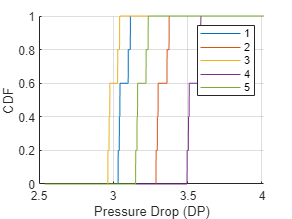

figure(1)
grid on, hold on
plot(x0, cdf_r{1})
plot(x0, cdf_r{2})
plot(x0, cdf_r{3})
plot(x0, cdf_r{4})
plot(x0, cdf_r{5})
        % here, 3 and 4 contains the max/min values
legend('1','2','3','4','5'), hold off
xlabel('Pressure Drop (DP)')
ylabel('CDF')

Now, for calculating area p-box, only the upper and lower bound of the above curves have to be taken. That would be-

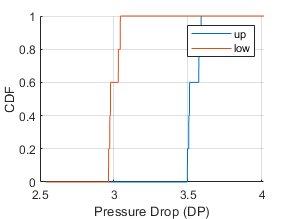

figure(2)
grid on, hold on
plot(x0, cdf_r{rmx})
plot(x0, cdf_r{rmn})
        % here, 3 and 4 contains the max/min values
legend('up','low'), hold off
xlabel('Pressure Drop (DP)')
ylabel('CDF')

### **P-Box, CDF Values, Normal Distribution**

Let's estimate the CDFs for the assumed mean(midpoint) and std

for i=1:1:n
    cdf_m{i} = cdf('Normal', x0, mid(i), sg_a(i));
end

Now, let's plot everything to find those CDFs

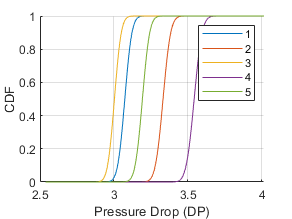

figure(3)
grid on, hold on
plot(x0, cdf_m{1})
plot(x0, cdf_m{2})
plot(x0, cdf_m{3})
plot(x0, cdf_m{4})
plot(x0, cdf_m{5})
legend('1','2','3','4','5'), hold off
xlabel('Pressure Drop (DP)')
ylabel('CDF')

Now, for building p-box, consider only upper and lower bound of the above curves.

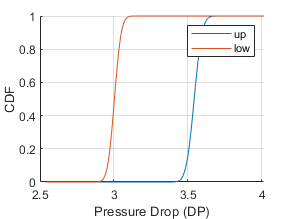

figure(4)
grid on, hold on
plot(x0, cdf_m{rmx})
plot(x0, cdf_m{rmn})
        % here, 3 and 4 contains the max/min values
legend('up','low'), hold off
xlabel('Pressure Drop (DP)')
ylabel('CDF')

### Prob 3.1, 1

Now, given that there's a singular experimental result. Which is-

The probabilty distribution would look like the follows-

% x0 = linspace(a, b, N+1);   % KPa
st1 = 3.12;        % step-value, from experimemt; KPa
%  tol = 1e-3;
for i=1:1:L
    cdf_e1(i) = stepf(x0(i), st1);
end
cdf_e1;

#### Method 1, for ND p-box

Now, let's plot the experimental values juxtaposed onto normal distribution (ND) p-box

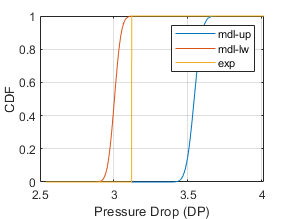

figure(5)
plot(x0, cdf_m{rmx}), grid on, hold on
plot(x0, cdf_m{rmn})
plot(x0, cdf_e1), hold off
legend('mdl-up', 'mdl-lw','exp')
xlabel('Pressure Drop (DP)')
ylabel('CDF')

**    Area Metric**

The following code could be employed to calculate area metric. To see the code-wise definition and algorithm of the function, please check 'Area Function' at the section '**Functions HW3, 03**'.

A11a = AreaM1(cdf_e1, cdf_m{rmn}, cdf_m{rmx}, dx);
A11a = round(A11a, 2)

A11a = 0

    (Ans)

#### Method 2, for SD p-box

Now, let's plot hte experimental values juxtaposed onto step distribution (SD) p-box

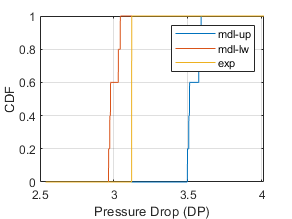

figure(6)
plot(x0, cdf_r{rmx}), grid on, hold on
plot(x0, cdf_r{rmn})
plot(x0, cdf_e1), hold off
legend('mdl-up', 'mdl-lw','exp')
xlabel('Pressure Drop (DP)')
ylabel('CDF')

    **Area Metric**

A11b = AreaM1(cdf_e1, cdf_r{rmn}, cdf_r{rmx}, dx)

A11b = 0

    (Ans)

#### Prob 3.1, 2

% x0 = linspace(a, b, N+1);   % KPa
st2 = 4.59;        % step-value, from experimemt; KPa
for i=1:1:L
    cdf_e12(i) = stepf(x0(i), st2);
end
cdf_e12;

#### Method 1, for ND p-box

Now, let's plot the experimental values juxtaposed onto P-box

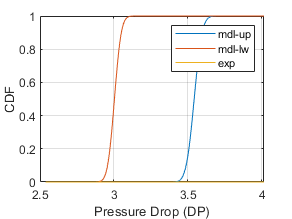

figure(7)
plot(x0, cdf_m{rmx}), grid on, hold on
plot(x0, cdf_m{rmn})
plot(x0, cdf_e12), hold off
legend('mdl-up', 'mdl-lw','exp')
xlabel('Pressure Drop (DP)')
ylabel('CDF')

    **Area Metric**

A12 = AreaM1(cdf_e12, cdf_m{rmn}, cdf_m{rmx}, dx);

The function-value of this problem is out of the graph. here, the highest value of the abscissa is b = 4.099; but here, DP = 4.59. So, we ahve to add something with the calculated area.

A12_x = (st2 - b)*1;
A12 = A12_x + A12

A12 = 1.0473

    (Ans)

### Prob 3.2

xp = [3.12, 2.92, 3.23, 2.84, 3.19];    % experimental values; KPa
xp = sort(xp);              % if  not sorted, won't be caught within abscissa
nv = 5;         % no. of experiments
for i=1:1:L
    cdf_e2(i) = stepf2(x0(i), xp);
end
cdf_e2;

#### Method 1, for ND p-box

Now, let's plot it

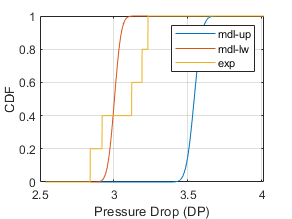

figure(8)
plot(x0, cdf_m{rmx}), grid on, hold on
plot(x0, cdf_m{rmn})
plot(x0, cdf_e2), hold off
legend('mdl-up', 'mdl-lw','exp')
xlabel('Pressure Drop (DP)')
ylabel('CDF')

**        Area Metric**

Now, let's find the area metric for this situation. Here, the shaded area represents the area metric.

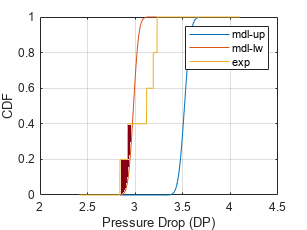

So, the area metric would be-

A2a = AreaM1(cdf_e2, cdf_m{rmn}, cdf_m{rmx}, dx)

A2a = 0.0352

    (Ans)

#### Method 2, for SD p-box

Let's plot it

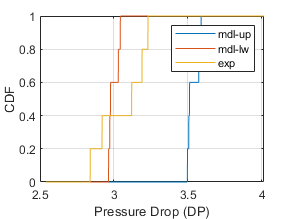

figure(9)
plot(x0, cdf_r{rmx}), grid on, hold on
plot(x0, cdf_r{rmn})
plot(x0, cdf_e2), hold off
legend('mdl-up', 'mdl-lw','exp')
xlabel('Pressure Drop (DP)')
ylabel('CDF')

**    Area Metric**

So, the area metric would be-

A2b = AreaM1(cdf_e2, cdf_r{rmn}, cdf_r{rmx}, dx)

A2b = 0.0351

    (Ans)

### **Prob 3.3**

xp = [3.12, 2.92, 3.23, 2.84, 3.19];    % experimental values; KPa
xp = sort(xp);
xp_u = xp*1.02;         % upper bounds; KPa
    xp_u = round(xp_u, 3);   % rounding up
        % if not rounded up won't be caught within abscissa points 
xp_l = xp*0.98;         % lower bounds
    xp_l = round(xp_l, 3);
nv = 5;

for i=1:1:L
    cdf_e3_u(i) = stepf2(x0(i), xp_u);
    cdf_e3_l(i) = stepf2(x0(i), xp_l);
end
cdf_e3_u;
cdf_e3_l;

#### Method 1, for ND p-box

Now, to plot this

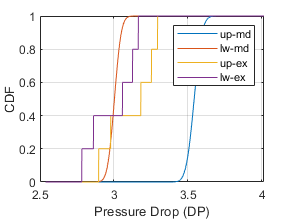

figure(10)
plot(x0, cdf_m{rmx}), grid on, hold on
plot(x0, cdf_m{rmn})
plot(x0, cdf_e3_u)
plot(x0, cdf_e3_l), hold off
legend('up-md','lw-md','up-ex','lw-ex')
xlabel('Pressure Drop (DP)')
ylabel('CDF')

**        Area Metric**

From the curve we can see the shaded area (show) would represent the area metric.

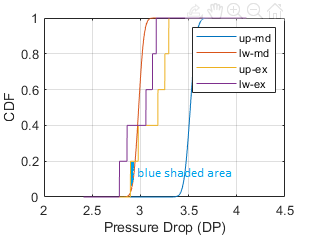

So, that would be the net positive area created by the upper-bound curve of the experiment with the lower-bound curve of the model.

A3a = AreaM2(cdf_e3_u, cdf_e3_l, cdf_m{rmn}, cdf_m{rmx}, dx)

A3a = 0.0122

    (Ans)

#### Method 2, for SD p-box

Now, to plot this

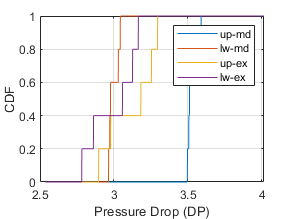

figure(11)
plot(x0, cdf_r{rmx}), grid on, hold on
plot(x0, cdf_r{rmn})
plot(x0, cdf_e3_u)
plot(x0, cdf_e3_l), hold off
legend('up-md','lw-md','up-ex','lw-ex')
xlabel('Pressure Drop (DP)')
ylabel('CDF')

**        Area Metric**

The area metric would be-

A3b = AreaM2(cdf_e3_u, cdf_e3_l, cdf_r{rmn}, cdf_r{rmx}, dx)

A3b = 0.0133

    (Ans)

It is seen that area metric values associated with both the methods are found to be approximately same. It is happened due to problem associated with discretization of the grid where higher precision values have been truncated.

### Functions HW3, 03 #### #### #### ####

**Step Function 1**

The following funciton returns the Cumulative Probability Distribution of single experimental outcome. 

function y = stepf(x, st)
        % st =  step value
    if x < st
        y = 0;
    else
        y = 1;
    end 
end 

**Step Function 2**

The following funciton returns the Cumulative Probability Distribution of five different experimental outcome. 

function y = stepf2(x, Xp)
% this assumes that all experimental values of vector Xp are different
    nv = length(Xp);

    if x < Xp(1)
        y = 0;          %## input
    elseif x >= Xp(1) && x < Xp(2)
        y = 1/nv;
    elseif x >= Xp(2) && x < Xp(3)
        y = 2/nv;
    elseif x >= Xp(3) && x < Xp(4)
        y = 3/nv;
    elseif x >= Xp(4) && x < Xp(5)
        y = 4/nv;
    else 
        y = 1;
    end
end

**Area Function 1**

function A = AreaM1(cdf_e, cdf_m_lw, cdf_m_up, dx)
    % cdf_e = cdf vector from experiment;
    % cdf_a = cdf vector from model
    % dx = grid size; L = length of grid-vector

The following loop calculates the green shaded area of the diagram.

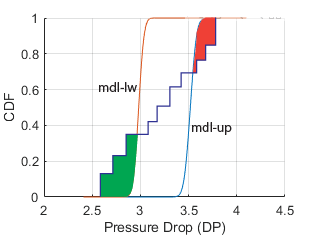

L =  length(cdf_e);
Df1 = cdf_e - cdf_m_lw;
  sum1 = 0;
for i=1:1:L-1  % trapezoidal method reduces 1 iteration
    if Df1(i) > 0        % fetching only positive values
        Y(i) = (Df1(i) + Df1(i+1))/2 *dx;  % trapezoidal method
        sum1 = Y(i) + sum1;
    else
        continue
    end
end
sum1 = round(sum1, 4);      % rounding up

The following loop calculates the red shaded area of the diagram.

Df2 = cdf_m_up - cdf_e;
  sum2 = 0;
for i=1:1:L-1
    if Df2(i) > 0        % fetching only positive values
        Y(i) = (Df2(i) + Df2(i+1))/2 *dx;  % trapezoidal method
        sum2= Y(i) + sum2;
    else
        continue
    end
end
sum2 = round(sum2, 4);

A = sum1 + sum2;

end

**Area Function 2**

function A = AreaM2(cdf_e_up, cdf_e_lw, cdf_m_lw, cdf_m_up, dx)
    % cdf_e = cdf vector from experiment;
    % cdf_a = cdf vector from model
    % dx = grid size; L = length of grid-vector

The following loop calculates the green shaded area of the diagram.

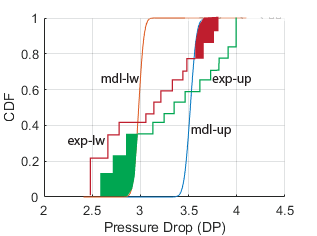

L =  length(cdf_e_up);
Df1 = cdf_e_up - cdf_m_lw;
  sum1 = 0;
for i=1:1:L-1  % trapezoidal method reduces 1 iteration
    if Df1(i) > 0        % fetching only positive values
        Y(i) = (Df1(i) + Df1(i+1))/2 *dx;  % trapezoidal method
        sum1 = Y(i) + sum1;
    else
        continue
    end
end
sum1 = round(sum1, 4);      % rounding up

The following loop calculates the red shaded area of the diagram.

Df2 = cdf_m_up - cdf_e_lw;
  sum2 = 0;
for i=1:1:L-1
    if Df2(i) > 0        % fetching only positive values
        Y(i) = (Df2(i) + Df2(i+1))/2 *dx;  % trapezoidal method
        sum2= Y(i) + sum2;
    else
        continue
    end
end
sum2 = round(sum2, 4);

A = sum1 + sum2;

end